start = [-8, -0.5, 1, 8];
f = @(x) 0.01 * sin (10 * x(1)) + (0.07 * x(1) ^ 2 - 0.4) ^ 2;
eps = 1.00e-04; gamma = 0.001;
max_iter = 1000;
alfa = 2;
e_step = 0.1

e_step = 0.1000

lg_x_min = -2.6100

lg_iter = 57

zp_x_min = -2.6106

zp_iter = 71

err = 5.6508e-04

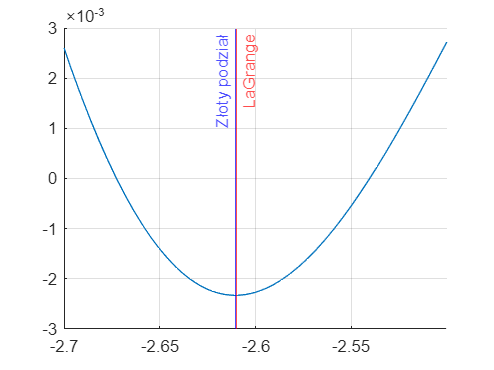

lg_x_min = -0.8890

lg_iter = 10

zp_x_min = -0.8884

zp_iter = 21

err = 5.4963e-04

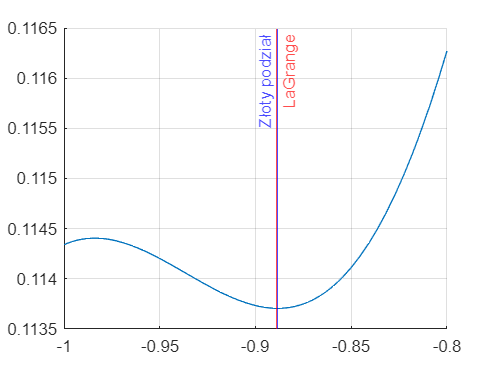

lg_x_min = 1.8296

lg_iter = 12

zp_x_min = 1.8293

zp_iter = 25

err = 3.2311e-04

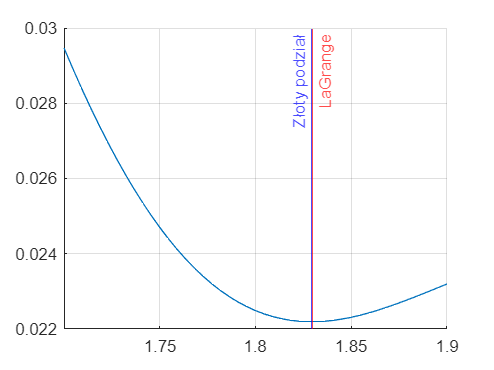

lg_x_min = 2.3624

lg_iter = 59

zp_x_min = 2.3624

zp_iter = 73

err = 4.6593e-06

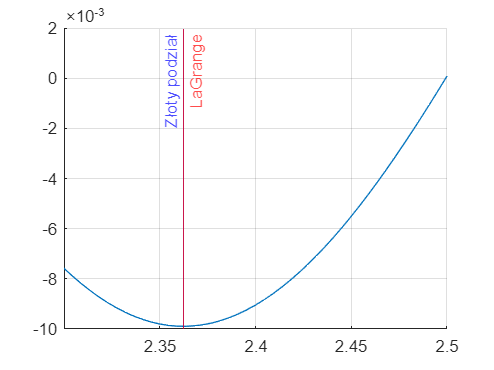


for i = [1:4]
    [a, b, e_iter] = expansion(f, start(i), start(i) + e_step, alfa, max_iter);

    figure; hold on;
    fplot(f, [a b]); grid on;

    [lg_x_min, lg_iter] = lagrange(f, a, b, (a + b) / 2, eps, gamma, max_iter);
    lg_x_min
    lg_iter = e_iter + lg_iter

    [zp_x_min, zp_iter] = z_podz(f, a, b, eps, max_iter);
    zp_x_min
    zp_iter = e_iter + zp_iter
    err = abs(lg_x_min - zp_x_min)

    xline(zp_x_min, 'b', label = "Złoty podział", LabelHorizontalAlignment="left"); 
    xline(lg_x_min, 'r', label = "LaGrange"); hold off; xlim([a b]);
end

% Definicja funkcji celu
f = @(x) x^2 + 2*x - 5;

% Kierunek 1: Punkt zero funkcji
direction_zero = [-1, 0];  % Kierunek w lewo

% Minimalizacja funkcji celu w kierunku direction_zero
x_zero = fminsearch(@(x) abs(f(x)), -1, optimset('TolFun', 1e-6));

fprintf('a) Punkt zero funkcji: x = %.4f, f(x) = %.4f\n', x_zero, f(x_zero));

a) Punkt zero funkcji: x = -3.4495, f(x) = -0.0000



% Kierunek 2: Punkt, dla którego funkcja przyjmuje wartość równą 1
direction_one = [1, 0];  % Kierunek w prawo

% Minimalizacja funkcji celu w kierunku direction_one, z ograniczeniem f(x) = 1
options = optimset('TolFun', 1e-6, 'TolCon', 1e-6);
[x_one, fval_one] = fminsearch(@(x) (f(x) - 1)^2, -2, options);

fprintf('b) Punkt dla f(x) = 1: x = %.4f, f(x) = %.4f\n', x_one, f(x_one));

b) Punkt dla f(x) = 1: x = -3.6457, f(x) = 0.9997


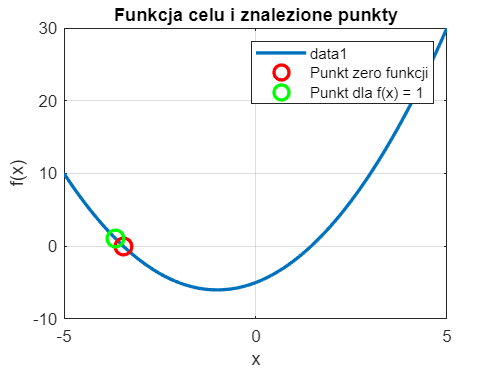


% Wykres funkcji
x_values = linspace(-5, 5, 100);
y_values = arrayfun(f, x_values);

figure;
plot(x_values, y_values, 'LineWidth', 2);
hold on;

% Zaznacz punkt zero funkcji
plot(x_zero, f(x_zero), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Punkt zero funkcji');

% Zaznacz punkt dla f(x) = 1
plot(x_one, f(x_one), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Punkt dla f(x) = 1');

legend();
xlabel('x');
ylabel('f(x)');
title('Funkcja celu i znalezione punkty');
grid on;
hold off;

% Definicja funkcji celu
f = @(x1, x2) 2.5 * (x1.^2 - x2).^2 + (1 - x1).^2;

% Współrzędne punktu początkowego i końcowego
x1_0 = 0.25;
x2_0 = 0.5;
x1_1 = -0.1;
x2_1 = -0.1;

% Wektor kierunku
v = [x1_1 - x1_0, x2_1 - x2_0];

% Parametry funkcji jednej zmiennej
x1_t = @(t) x1_0 + t * v(1);
x2_t = @(t) x2_0 + t * v(2);

% Funkcja celu jako funkcja jednej zmiennej
g = @(t) f(x1_t(t), x2_t(t));

% Wykres funkcji celu
figure;
fsurf(f, [-0.5, 0.5, -0.5, 0.5], 'FaceAlpha', 0.6, 'DisplayName', 'Funkcja celu');
hold on;

% Wykres punktu startowego
plot3(x1_0, x2_0, f(x1_0, x2_0), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Start');

% Minimalizacja funkcji jednej zmiennej
t_min = fminsearch(g, 0);

% Współrzędne punktu minimalnego
x1_min = x1_t(t_min)

x1_min = 0.1033

x2_min = x2_t(t_min)

x2_min = 0.2486

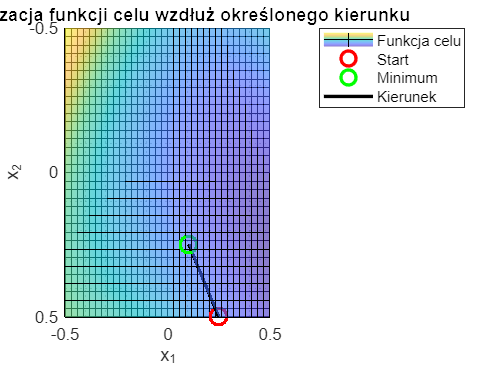


% Wykres punktu minimalnego
plot3(x1_min, x2_min, g(t_min), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Minimum');

% Linia przedstawiająca kierunek
plot3(x1_t([0, t_min]), x2_t([0, t_min]), g([0, t_min]), 'k-', 'LineWidth', 2, 'DisplayName', 'Kierunek');

% Legenda i etykiety osi
legend();
xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1, x_2)');
title('Minimalizacja funkcji celu wzdłuż określonego kierunku');
grid on;
view(0, -90);
grid minor;  % Dodane aby zmniejszyć intensywność siatki
hold off;

px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5;
W = polyfit(px, py, stopien);

f = @(x) (0.05*sin(1*x)+W(1)*x^stopien+W(2)*x^(stopien-1)+W(3)*x^(stopien-2)+W(4)*x^(stopien-3)+W(5)*x^(stopien-4)+W(6)*x^(stopien-5))*(0.001*sin(x/10))+0.000001*x;
eps = 0.05; gamma = 0.001;
max_iter = 1000;

a = -0.2750; b = 0.0063;

[lg_x_min, lg_iter] = lagrange(f, a, b, (a + b) / 2, eps, gamma, max_iter);
lg_x_min

lg_x_min = -0.1004



[zp_x_min, zp_iter] = z_podz(f, a, b, eps, max_iter);
zp_x_min

zp_x_min = -0.1060


err = abs(lg_x_min - zp_x_min)

err = 0.0056

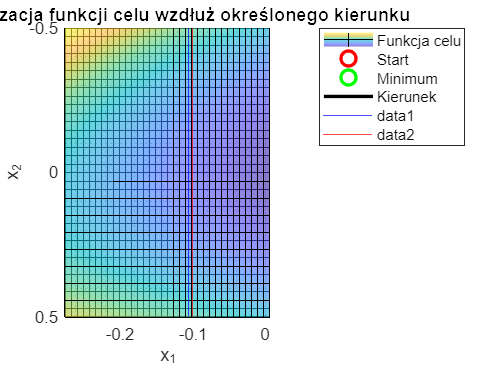


xline(zp_x_min, 'b', label = "Złoty podział", LabelHorizontalAlignment="left"); 
xline(lg_x_min, 'r', label = "LaGrange"); hold off; xlim([a b]);

global y; global t; global k;

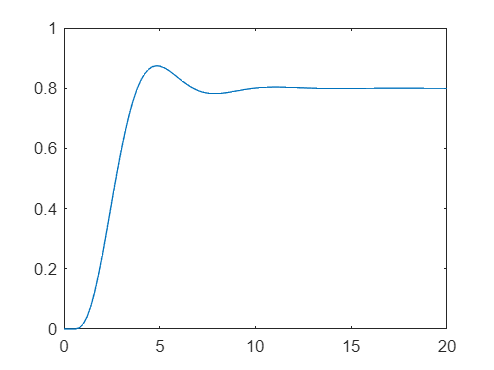


G1 = tf([0 1], [1 2 2.25 1.25]);
[G1p_Licz, G1p_mian] = pade(0.5, 3);
G1p = tf(G1p_Licz, G1p_mian);
G1f = series(G1, G1p);
t = 0:0.2:20;
y = step(t, G1f);
plot(t, y);



k = 0.8 % Wartość odczytana z wykresu

k = 0.8000

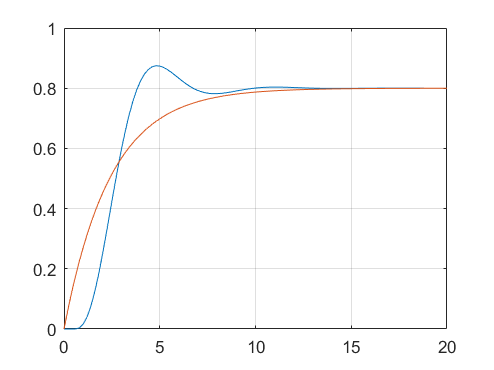

ident_T = 2.4240

blad = 0.0090

T = 3; % przybliżona wartość odczytana z wykresu

G2 = tf(k, [T 1]);

[ident_T, blad] = fminsearch(@ident, T)

function blad = ident(T)
    global y; global t; global k;
    obiekt = tf(k, [T 1]);
    y_sym = step(obiekt, t);
    plot(t, y, t, y_sym);
    grid on;
    drawnow;
    pause(0.1);
    e = y - y_sym;
    blad = sum(e.^2) / length(e);
end